clear
close all
hold off

%Desviación estándar es v=2
v=2;
%Desviación en la formación de robots es delta=0.1
delta=0.1;


N=4; %Número de robots (a partir de N=6 buena aproximación)
iteration=500; %Número de iteraciones
step_size=0.1;
D=5; %Radio de la formación
S=10^-4*[2,1;1,1]; %Matriz
c0_initial=[20;20]; %Posición del centro inicial (initial guess)
r0=[0 0]'; %Centro de contaminación
e=[1;0];

w0=1; %Movimiento circular de un radián por segundo

colors=["ob","ok","or","oy","og","om","oc","ob"];
tf=20;
t=linspace(0,tf,iteration);

%Condiciones iniciales
c(:,1)=c0_initial;
r_c(:,1)=c(:,1)-r0;
mod_r_c(1)=norm(r_c(:,1));
simulation=5; %número de simulaciones
mod_rc=zeros(iteration,simulation);

Aquí se representa la media y la desviación estándar después de todas las simulaciones. Se ha considerado solo el ruido en la medida en este caso.

%Se aplica el método del gradiente
for k=1:simulation
    c0=c0_initial;
    for i=1:iteration
        %Aproximación del gradiente en el 
  
        grad_centr(:,i)=-gradient_point2D_ruido(c0,t(i),N,D,S,w0,v,delta);
        %Aplicación del método del gradiente ascendente
        c(:,i)=c0+step_size*grad_centr(:,i);
        c0=c(:,i);
        %Sacar el módulo de la diferencia entre el centro y el punto de
        %contaminación para cada iteración
        mod_r_c(i)=norm(c0-r0); 
    end
    mod_rc(:,k)=mod_r_c;
end


Representación de la media y la desviación estándar:

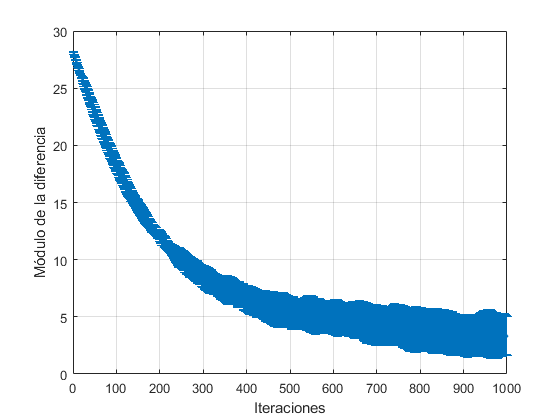

for h=1:iteration
    media(h)=mean(mod_rc(h,:));
    desv_std(h)=std(mod_rc(h,:));
end
errorbar(1:iteration,media,desv_std,'.')
xlabel('Iteraciones')
ylabel('Módulo de la diferencia')
grid on

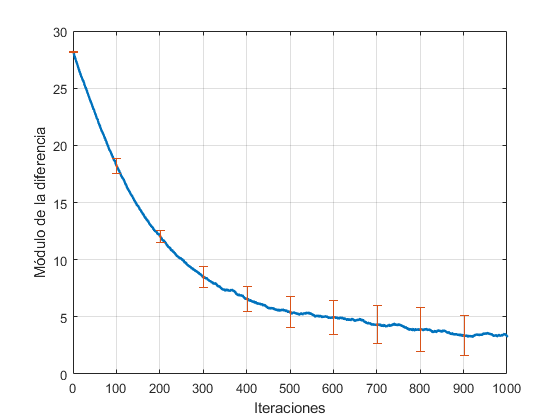


plot(1:iteration,media,'.')
hold on
puntos=1:100:1000;
errorbar(puntos,media(puntos),desv_std(puntos),'.')
xlabel('Iteraciones')
ylabel('Módulo de la diferencia')
grid on